# Tipos de datos: Caracteres y cadenas

Los *arreglos caracter* (también llamados **char array**) y los *arreglos cadena* (también llamados **string array**) permiten guardar texto. Sin embargo, a diferencia de otros lenguajes de programación, en MATLAB hay una enorme diferencia entre un *arreglo caracter* y un *arreglo cadena*.

Un *arreglo caracter* (**char array**) es una secuencia de caracteres, al igual que un arreglo numérico es una secuencia de números. Un uso típico es almacenar fragmentos cortos de texto como vectores de caracteres, por ejemplo, `c = 'Proyecto Ingenecia'`.

Un *arreglo cadena* (**string array**) es un contenedor para fragmentos de texto. Estos arreglos proporcionan un conjunto de funciones para trabajar con texto como datos.

**Figura 1.** Arreglo caracter VS. Arreglo cadena.

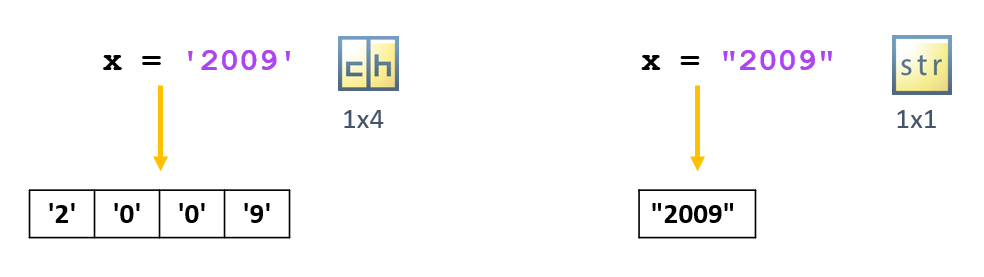

*Tomado de la documentación oficial de MATLAB.*

#### Observación

A partir de la versión R2017a es posible crear cadenas usando comillas dobles, por ejemplo, `str = "Saludos, amigo"`. En versiones anteriores se debe utilizar la función `string` para crear una cadena.

## Funciones de creación y conversión

Existen diversas funciones para crear o convertir diferentes tipos de variables en cadenas o arreglos de caracteres. A continuación se detallan las más usuales.

### Función `char` o `''`

Para crear un arreglo caracter se utiliza la función `char` o apóstrofes `''`.

clear
a= 'hola '

a = 'hola '

b = 'HOLAd' %La diferencia está en la dimensión, es mejor arreglo cadena

b = 'HOLAd'

char hoal

ans = 'hoal'

[a;b]

ans = 2x5 char array
    'hola '
    'HOLAd'


### Función `string` o `""`

Para crear una cadena se utiliza la función `string` o apóstrofes `""`.

string hola

ans = "hola"

clear
a= "hola"

a = "hola"

b = "HOLAd" %La diferencia está en la dimensión, es mejor arreglo cadena

b = "HOLAd"

[a b]

ans = 1x2 string array
    "hola"    "HOLAd"


### Funciones `str2double` y `double`

La función `str2double` permite crear un número tipo double a partir de una cadena. Es decir, convierte una cadena en un número.

a = "124423"

a = "124423"

b = str2double(a)

b = 124423

La función `double` es similar a la función `str2double`.

c = double(a)

c = 124423

#### Observación

Si la cadena que se ingresa no es un número, entonces las funciones `str2double` y `double` devolverán un `NaN` (**N**ot **a** **N**umber).

a = "mfekfwk"

a = "mfekfwk"

b = double(a)

b = NaN

### Función `num2str`

La función `num2str` permite crear un arreglo caracter a partir de un número. Es decir, convierte un número en un arreglo caracter.

a = 30432

a = 30432

b = string(num2str(a)) %String me sirve para hacer una conversión de caracter a cadena y chart de la misma manera

b = "30432"

## Funciones de concatenación

Existen diversas funciones para concatenar (unir) cadenas o arreglos de caracteres. A continuación se detallan las más usuales.

### Función `plus` o `+`

Las funciones de suma para números permiten concatenar únicamente cadenas.

a = "hola "

a = "hola "

b = "como estas?"

b = "como estas?"

c = a + b

c = "hola como estas?"

#### Observación

La función `plus` o `+` sólo sirve con cadenas. Para concatenar arreglos de caracteres se utiliza la función `append`.

### Función `append`

La función `append` permite concatenar cadenas y arreglos de caracteres.

a = "hola ";
b = "como estas?";
c = append(a,b)

c = "hola como estas?"

f = 'hola ';
r = 'como estas?';
t = append(f,r)

t = 'hola como estas?'

### Función `strcat`

La fución `strcat`, al igual que la función `append`, permite concatenar cadenas y arreglos de caracteres horizontalmente.

a = "hola ";
b = "como estas?";
c = strcat(a,b)

c = "hola como estas?"

f = 'hola ';
r = ' como estas?';
t = strcat(f,r)

t = 'hola como estas?'

#### ¿Cuál es la diferencia entre la función `append` y la función `strcat`?

Si se concatenan arreglos de caracteres, la función `append` mantiene los espacios en blanco al final del arreglo caracter, mientras que la función `strcat` los elimina.

a = 'hola ';
b = 'como estas? ';
c = strcat(a,b) % No se mantiene el espacio 

c = 'holacomo estas?'

t = append(a,b) %Se mantiene el espacio 

t = 'hola como estas? '

## Material adicional

- [Caracteres y cadenas](https://www.mathworks.com/help/matlab/characters-and-strings.html)

- [Preguntas frecuentes sobre arreglos cadena](https://www.mathworks.com/help/matlab/matlab_prog/frequently-asked-questions-about-string-arrays.html)